# 2. iDMRG (infinite-size Density Matrix Renormalization Group)

Author: 조성주,  최윤식

## Problem

In this project, we are going to implement the infinite-size DMRG (iDMRG) for the anti-ferromagnetic S = 1/2 Heisenberg chain with open boundary conditions,


$$\hat{H}_\text{Heisenberg} = \sum_{\langle ij\rangle} \left[ \hat{{S}}_i^z  \hat{S}_j^z + \frac{1}{2} (\hat{S}_i^+ \hat{S}_j^-+\hat{S}_i^- \hat{S}_j^+) \right],$$


and the Ising model in a transverse field with open boundary conditions,


$$\hat{H}_\text{Ising} = \sum_{\langle ij\rangle}  \hat{{S}}_i^z  \hat{S}_j^z + \lambda\sum_i \hat S_i^x ,$$
				

where $\hat{\;S_i }$ are local spin-1/2 operators on site i. Here we refer to the figures and equations of Ref. 1. 

References			

[1] I. P. McCulloch, [arXiv:0804.2509 (2008)](https://arxiv.org/abs/0804.2509).

[2] S. R. White, [Phys. Rev. Lett. 69, 2863 (1992)](https://journals.aps.org/prl/abstract/10.1103/PhysRevLett.69.2863). 

clear

% iDMRG parameters
Nkeep = 30;
Nstep = 500;

% model definition
J=1;
lamb = 1;

% Hamiltonian
[S,I] = getLocalSpace('Spin',1/2);
H_H = contract(S,3,3,permute(conj(S),[2 1 3]),3,3); % Heisenberg
H_I = contract(S(:,:,2),3,3,conj(S(:,:,2)),3,3); % Ising
H_I = H_I + lamb * sqrt(2)*(contract(S(:,:,1),3,3,1,3,3)+contract(S(:,:,3),3,3,1,3,3)); % transverse field

% Hamiltonian in MPO representation
H_MPO = cell(1,2);

% Heisenberg model
Hloc = cell(5,5);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
for ito = (1:size(S,3)) % different components of spin operators
    Hloc{ito+1,1} = S(:,:,ito);
    Hloc{end,ito+1} = J*S(:,:,ito)';
end
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));
H_MPO{1} = Hloc;

% transverse field model

Hloc = cell(5,5);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
for ito = (1:size(S,3)) % different components of spin operators
    Hloc{ito+1,1} = S(:,:,ito);
end
Hloc{end,3} = S(:,:,2)';  % Sz Ising interaction
Hloc{end,2} = lamb*I/sqrt(2);   % transverse field
Hloc{end,4} = lamb*I/sqrt(2);

Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));
H_MPO{2} = Hloc;



## Point of Interest

- compare with Vidal's iTEBD : faster convergence because power method is not an efficient eigensolver. And Trotter decomposition requires careful scaling of time-step to zero for convergence.

- advantage of using MPS

- advantage of using MPO

## a)

Implement the iDMRG for translation invariant systems of a two-site unit cell. The procedure is summarized in Fig. 1. 		

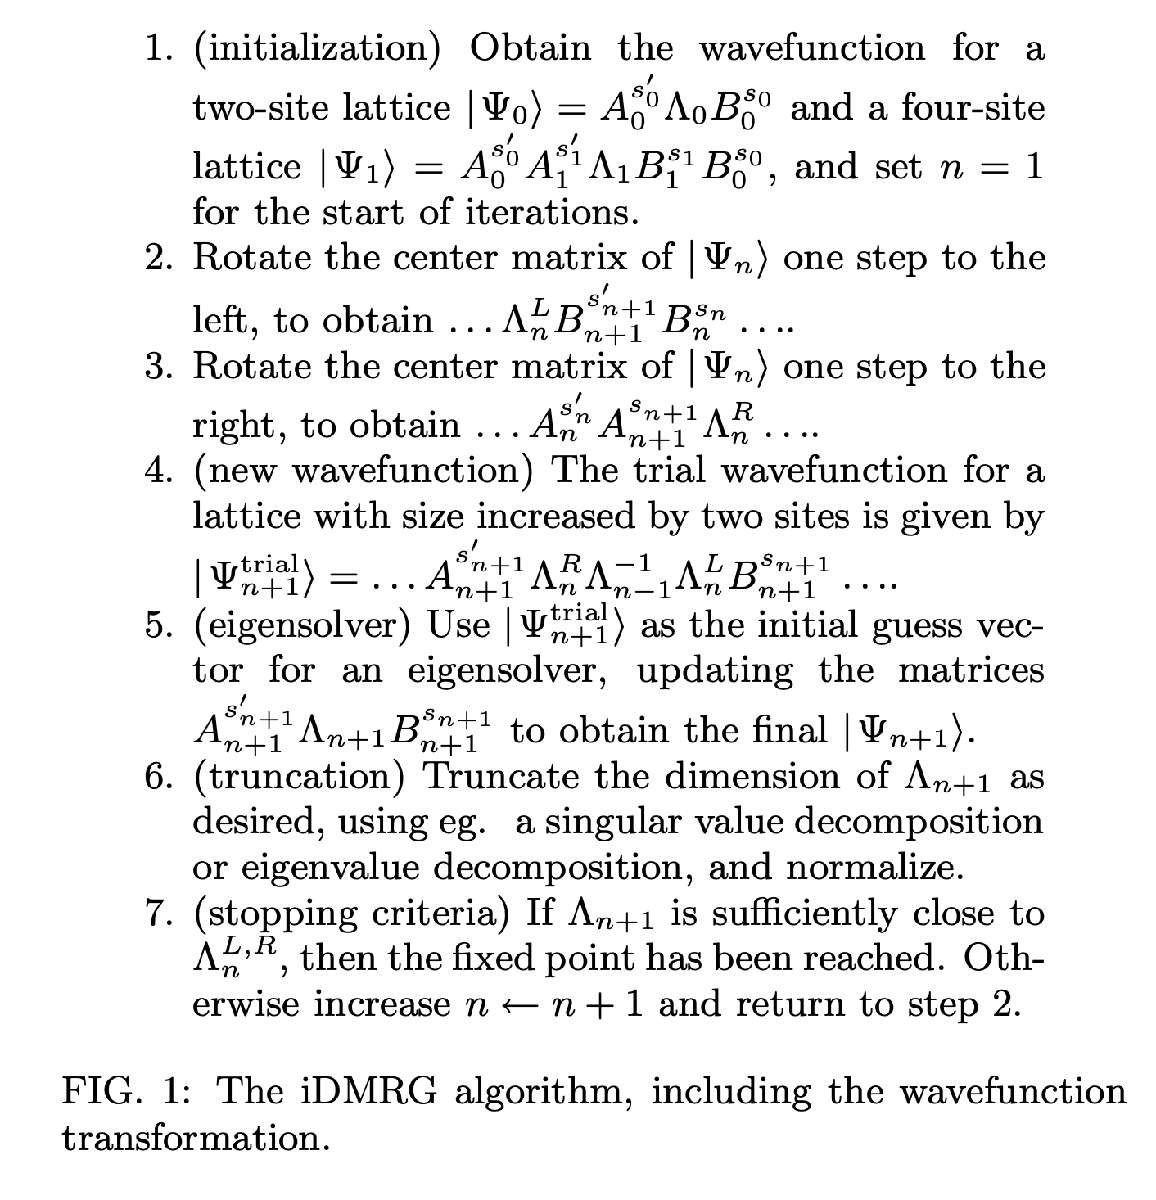		

D_list = [20 30 40 50];
Eiters = cell(2,numel(D_list));
Fid_iters = cell(2,numel(D_list));
for its = (1:2)
    H_loc = H_MPO{its};
    for itD = (1:numel(D_list))
        Nkeep = D_list(itD)

        % 1. initialize wavefunction
        % Initialize with random Lambda and Gamma
        Lambda_init = rand(Nkeep,1);
        A_init = rand(Nkeep,Nkeep,size(I,2));
        B_init = rand(Nkeep,Nkeep,size(I,2));
        
        % 2~7 loop : in function iDMRG_GS.m
        [A,B,Lambda,Eiters{its,itD},Fid_iters{its,itD}] = iDMRG_GS(A_init,B_init,Lambda_init,H_loc,Nkeep,Nstep);

    end
end

Nkeep = 20

22-12-01 17:11:41 | iDMRG: ground state search
22-12-01 17:11:41 | Nkeep = 20, # of steps = 20
Elapsed time: 0.2712s, CPU time: 1.37s, Avg # of cores: 5.052


Nkeep = 30

22-12-01 17:11:41 | iDMRG: ground state search
22-12-01 17:11:41 | Nkeep = 30, # of steps = 20
Elapsed time: 0.329s, CPU time: 1.74s, Avg # of cores: 5.289


Nkeep = 40

22-12-01 17:11:41 | iDMRG: ground state search
22-12-01 17:11:41 | Nkeep = 40, # of steps = 20
Elapsed time: 0.4296s, CPU time: 2.37s, Avg # of cores: 5.517


Nkeep = 50

22-12-01 17:11:42 | iDMRG: ground state search
22-12-01 17:11:42 | Nkeep = 50, # of steps = 20
Elapsed time: 0.5486s, CPU time: 3.05s, Avg # of cores: 5.56


Nkeep = 20

22-12-01 17:11:42 | iDMRG: ground state search
22-12-01 17:11:42 | Nkeep = 20, # of steps = 20
Elapsed time: 0.2371s, CPU time: 1.19s, Avg # of cores: 5.019


Nkeep = 30

22-12-01 17:11:42 | iDMRG: ground state search
22-12-01 17:11:42 | Nkeep = 30, # of steps = 20
Elapsed time: 0.3073s, CPU time: 1.68s, Avg # of cores: 5.467


Nkeep = 40

22-12-01 17:11:43 | iDMRG: ground state search
22-12-01 17:11:43 | Nkeep = 40, # of steps = 20
Elapsed time: 0.4677s, CPU time: 2.35s, Avg # of cores: 5.025


Nkeep = 50

22-12-01 17:11:43 | iDMRG: ground state search
22-12-01 17:11:43 | Nkeep = 50, # of steps = 20
Elapsed time: 0.6105s, CPU time: 3.23s, Avg # of cores: 5.291


## b)

Benchmark your implementation by computing the ground state energy per site for the Heisenberg model and compare with the exact result for an infinite chain $e_0 = (1/4)-\ln(2)$ [2]. The energy per site $e_0$can be extracted from the difference between total energies $E_0
$ for two consecutive iDMRG iteration, $e_0 \left(N\right)=\frac{\left\lbrack E_0 \left(N\right)-E_0 \left(N-2\right)\right\rbrack }{2}$ . Check your results with different bond dimensions D = 20, 30, 40, 50. (With D = 20 or 50, you would be able to achieve decent accuracy in energy $\approx {10}^{-4}$ or ${10}^{-5}$,respectively.)

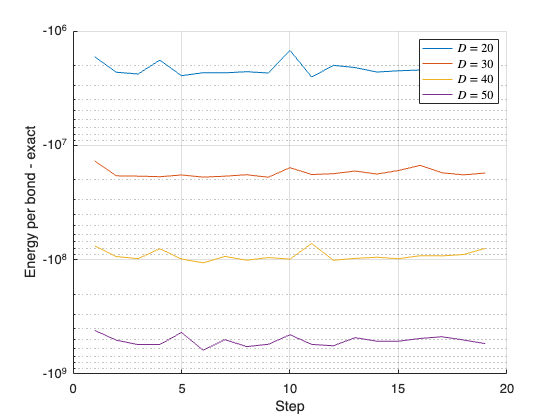


% for Heisenberg model
figure;
legs = cell([1 size(Eiters,2)]);
hold on;
Eexact = 1/4-log(2);
for itD = (1:size(Eiters,2))
    plot((1:size(Eiters{1,itD},2)-1),(Eiters{1,itD}(2:end)-Eiters{1,itD}(1:end-1))/2-Eexact,'LineWidth',1);
    legs{itD} = ['$D = ', ...
        sprintf('%i',D_list(itD)),'$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond - exact');
legend(legs{:},'Interpreter','latex');
grid on;

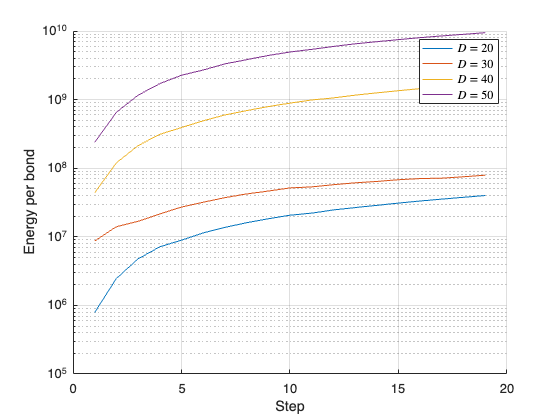

% for Ising model
figure;
legs = cell([1 size(Eiters,2)]);
hold on;
for itD = (1:size(Eiters,2))
    plot((1:size(Eiters{2,itD},2)-1),(Eiters{2,itD}(2:end)-Eiters{1,itD}(1:end-1))/2,'LineWidth',1);
    legs{itD} = ['$D = ', ...
        sprintf('%i',D_list(itD)),'$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond');
legend(legs{:},'Interpreter','latex');
grid on;

% compare with iTEBD




figure;
legs = cell(size(Eiters));
hold on;
for itt = (1:numel(Eiters))
    Eiter2 = reshape(permute(Eiters{itt},[2 1 3]), ...
        [size(Eiters{itt},2)*size(Eiters{itt},1) size(Eiters{itt},3)]);
    plot((1:size(Eiter2,1)).'/2,mean(Eiter2,2)-Eexact,'LineWidth',1);
    legs{itt} = ['$\tau_\mathrm{fin} = 10^{', ...
        sprintf('%i',log10(tau_fins(itt))),'}$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Energy per bond - exact energy');
legend(legs{:},'Interpreter','latex');
grid on;

## c)

Verify the claim in Ref. 1 that the trial wave function used in the step 4 of Fig. 1 is a good choice, by computing the fidelity $1-\langle \;\Psi {\;}_n^{\textrm{trial}} |\Psi {\;}_n \rangle \;$. Make a plot similar to Fig. 2 for the Heisenberg model. 						

	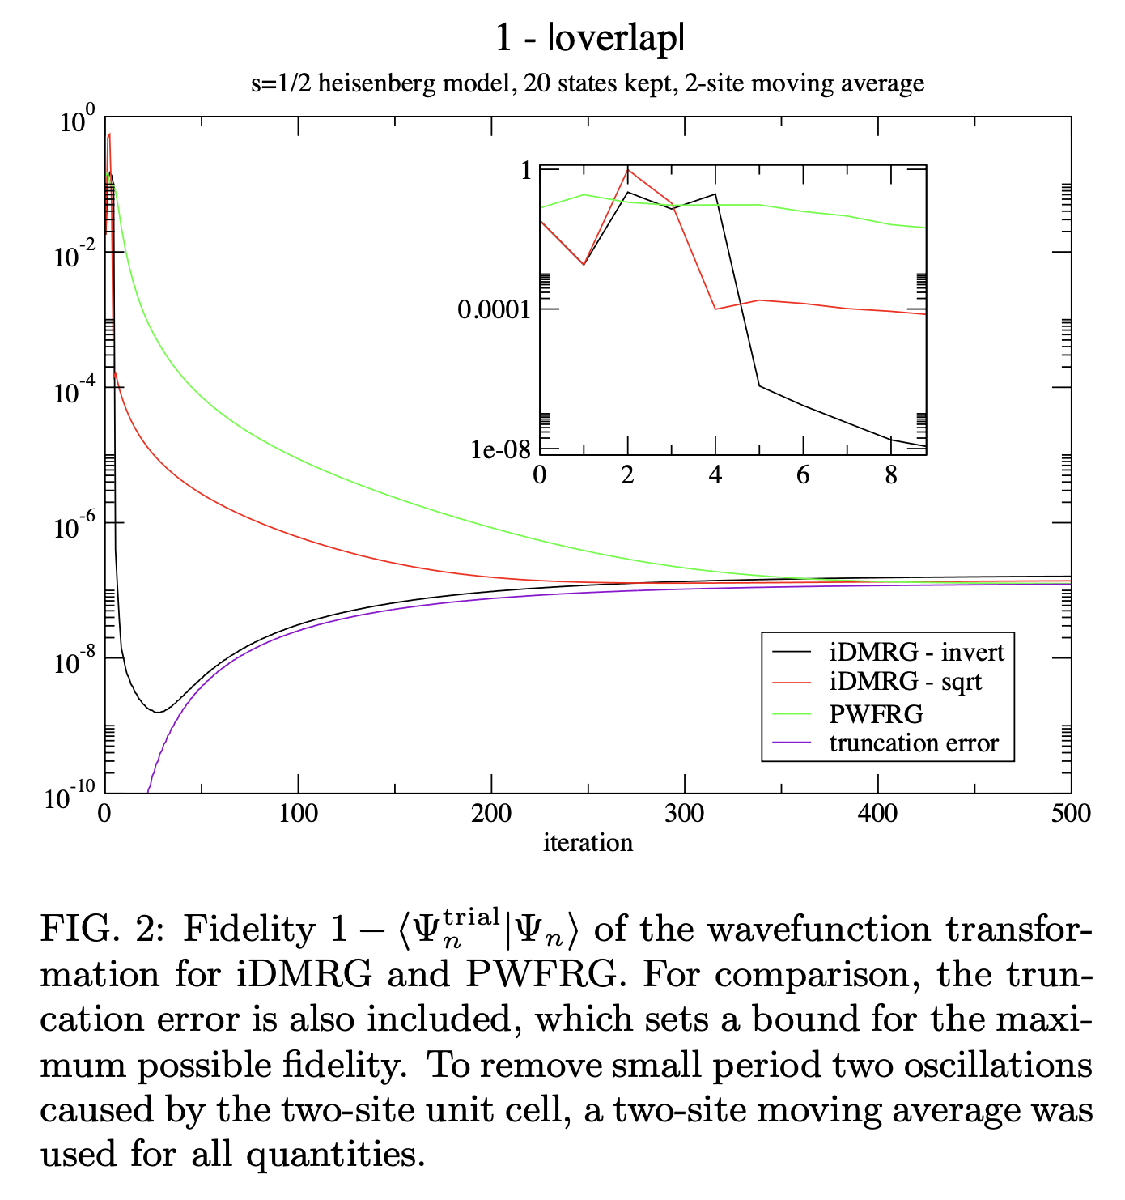

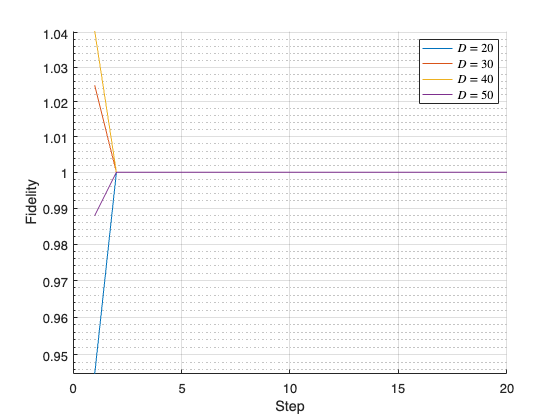

% for Heisenberg model
figure;
legs = cell([1 size(Fid_iters,2)]);
hold on;
for itD = (1:size(Fid_iters,2))
    plot((1:size(Fid_iters{1,itD},2)),Fid_iters{1,itD},'LineWidth',1);
    legs{itD} = ['$D = ', ...
        sprintf('%i',D_list(itD)),'$'];
end
hold off;
set(gca,'YScale','log','LineWidth',1,'FontSize',13);
xlabel('Step');
ylabel('Fidelity');
legend(legs{:},'Interpreter','latex');
grid on;

## d)

Analyze the behavior of iDMRG for the Ising model at the critical point $\lambda$=1/2 by studying the spectrum of the transfer operator [see Eq. (28)]. Make a plot similar to Fig. 4. 							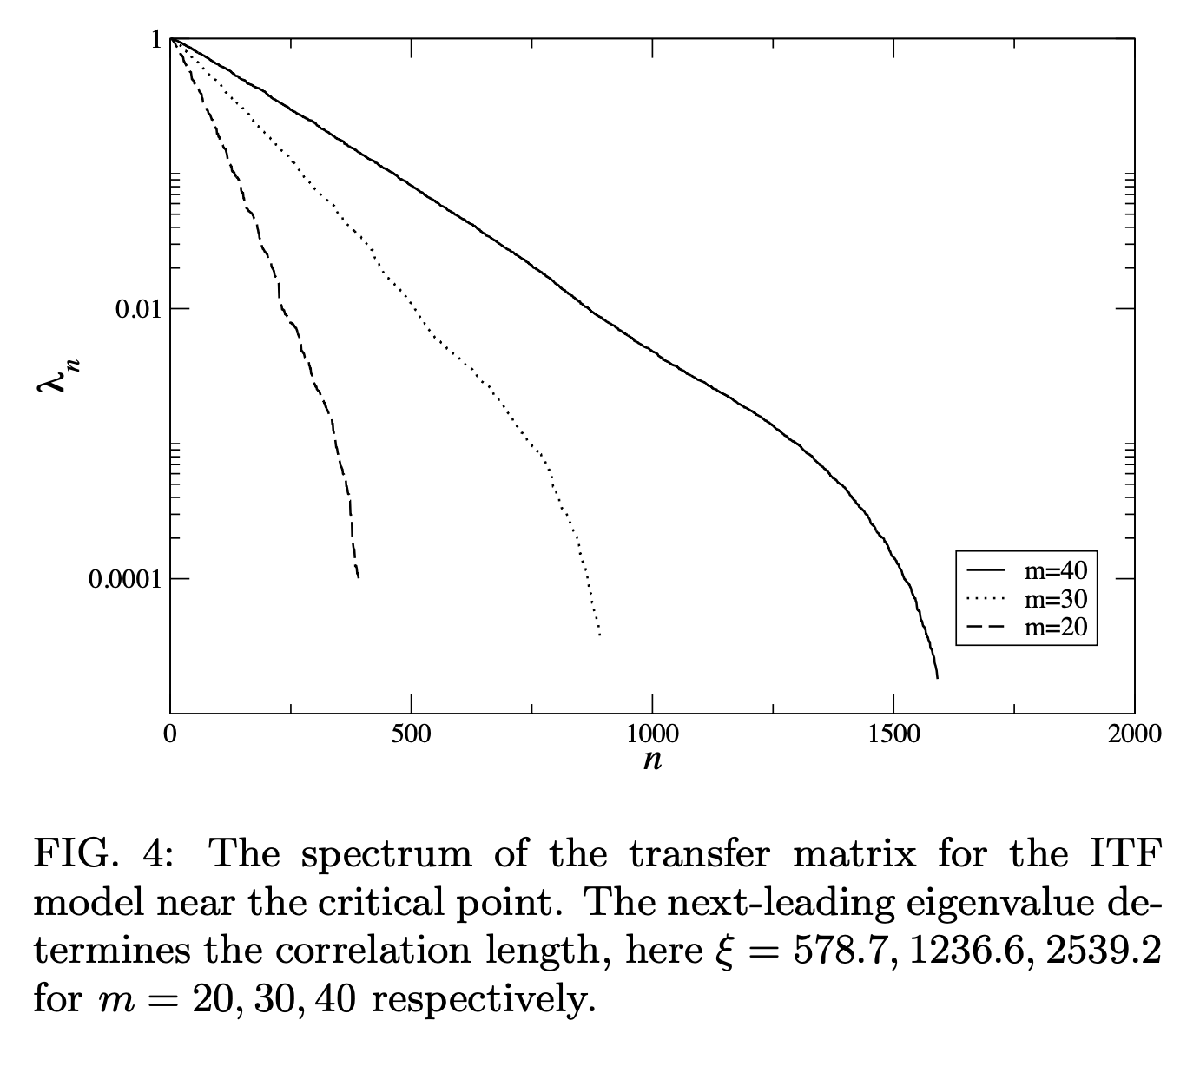		

## comparing with iTEBD